# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} \mathbb{E}_0\left(U\right) =  \mathbb{E}_0\left[\sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma}\right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$ and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. You will gradually extend, solve, and simulate this model. When simulating the model, initialize the state variables, including age: for the endogenous state variables, assume equal probabilities for each state; for any exogenous Markov process, draw from the stationary distribution. In each simulation, you must have a panel of 1000 consumers over 30 periods. 

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_0\left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \beta \left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


which reduces the choice space to $a_{t+1}$.

## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\ThinkBook\OneDrive - Fulbright University Vietnam\Desktop\code ps2\Matlab q1\Stochastic_export\Matlab - 1'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\ThinkBook\OneDrive - Fulbright University Vietnam\Desktop\code ps2\Matlab q1\Stochastic_export\Matlab - 1 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 6.9531 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

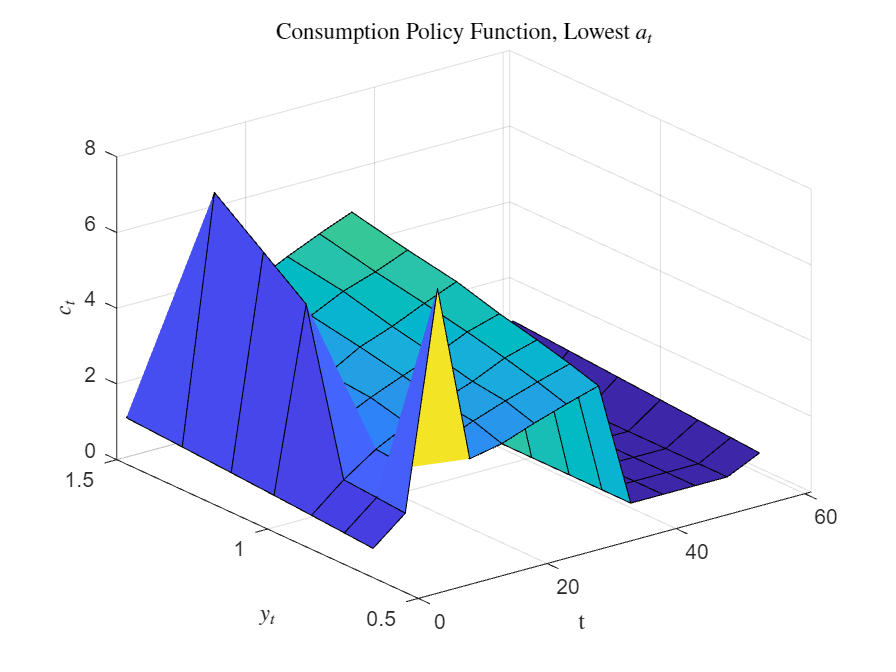

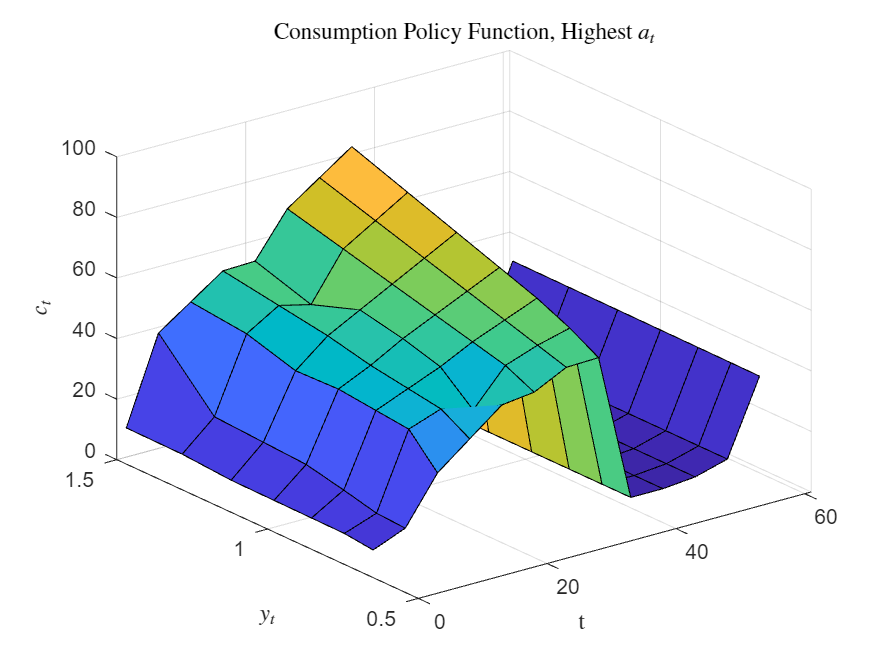

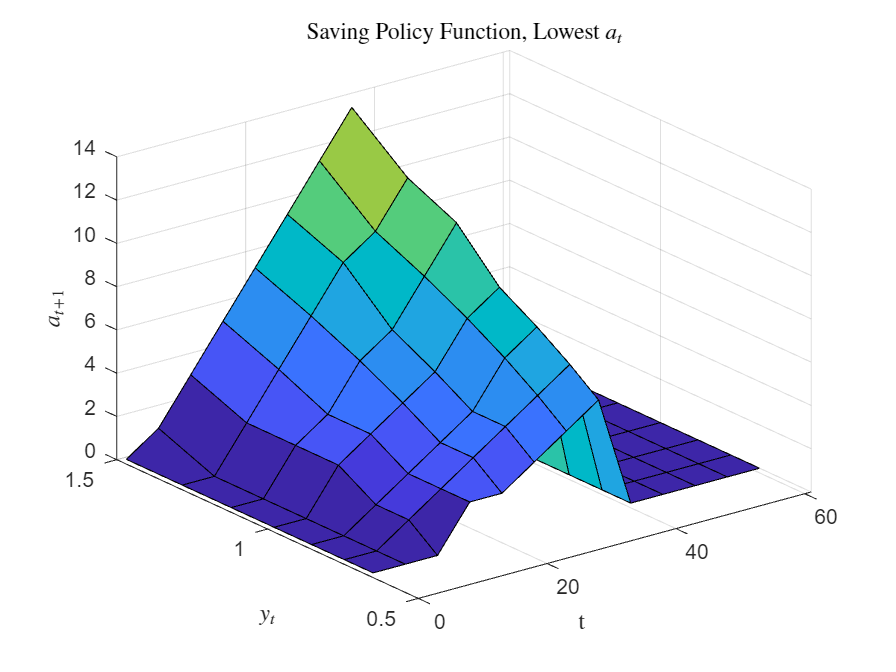

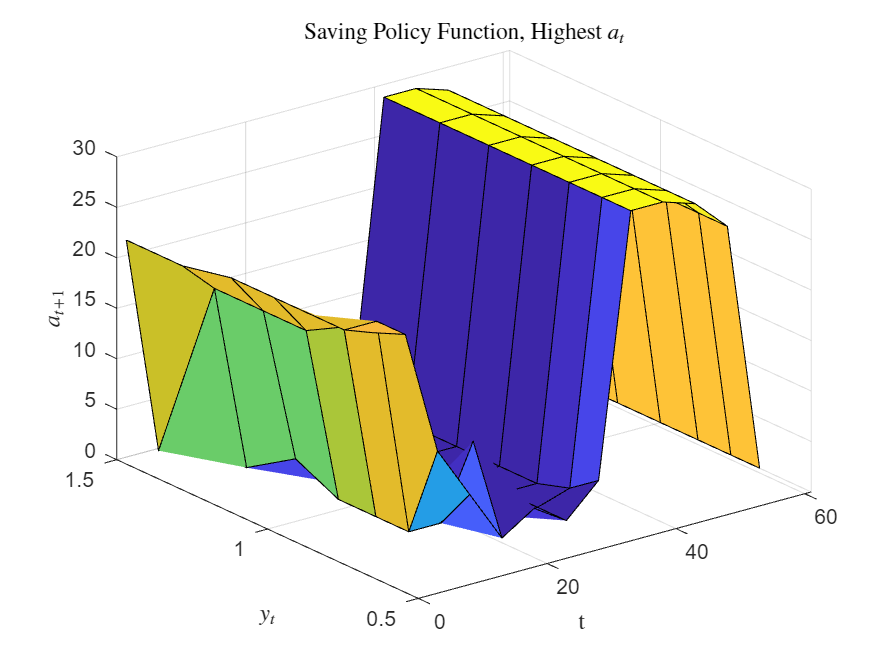

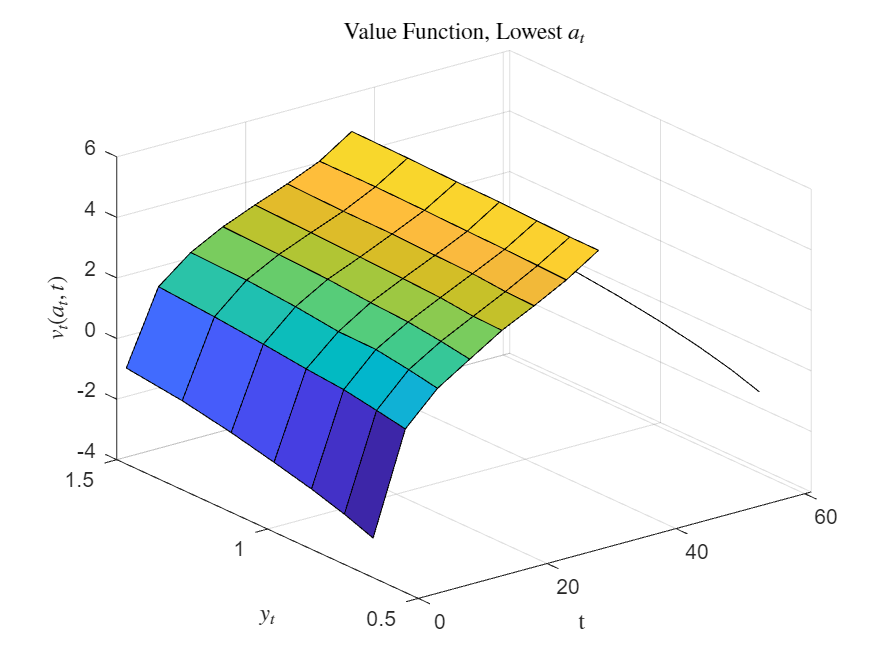

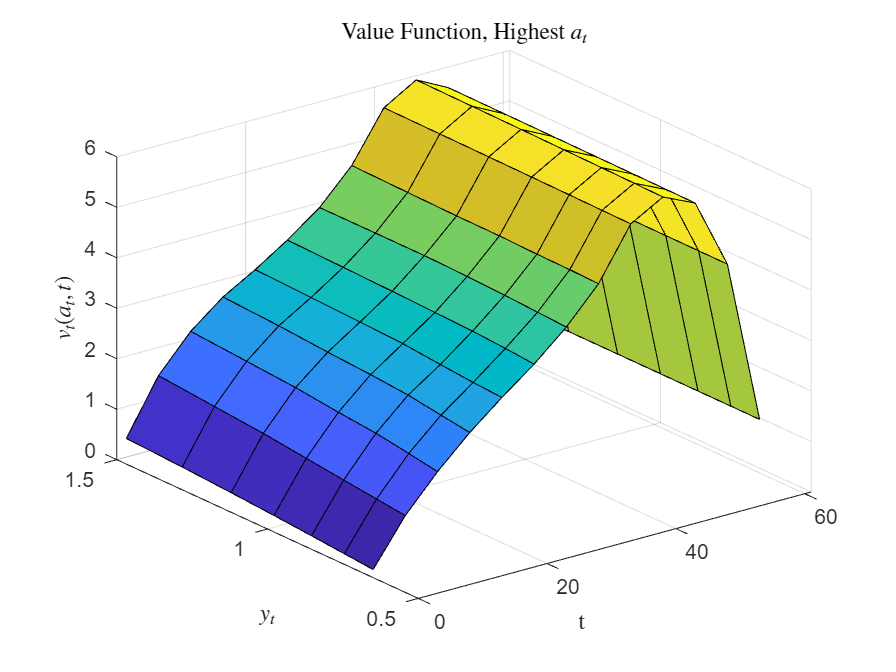

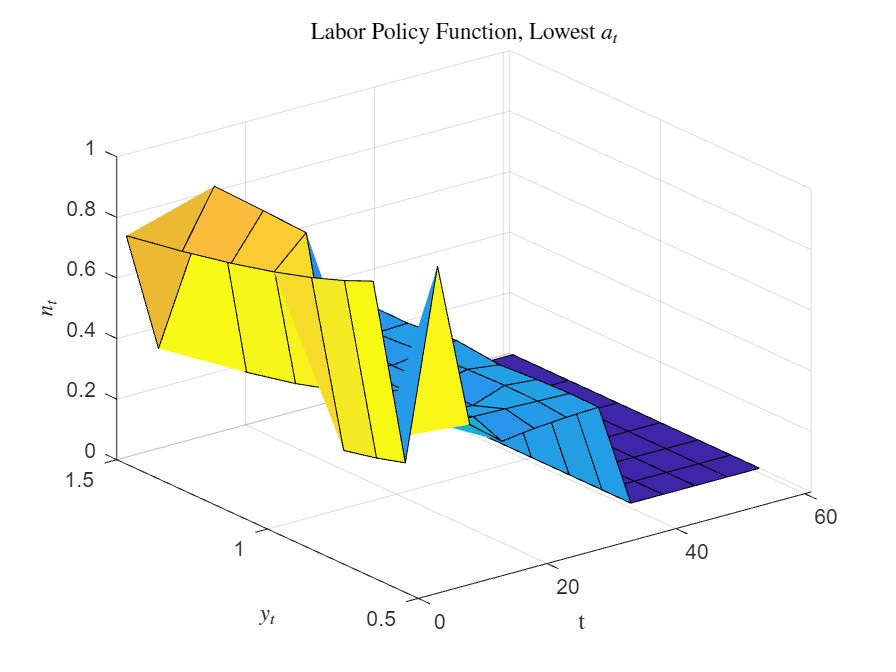

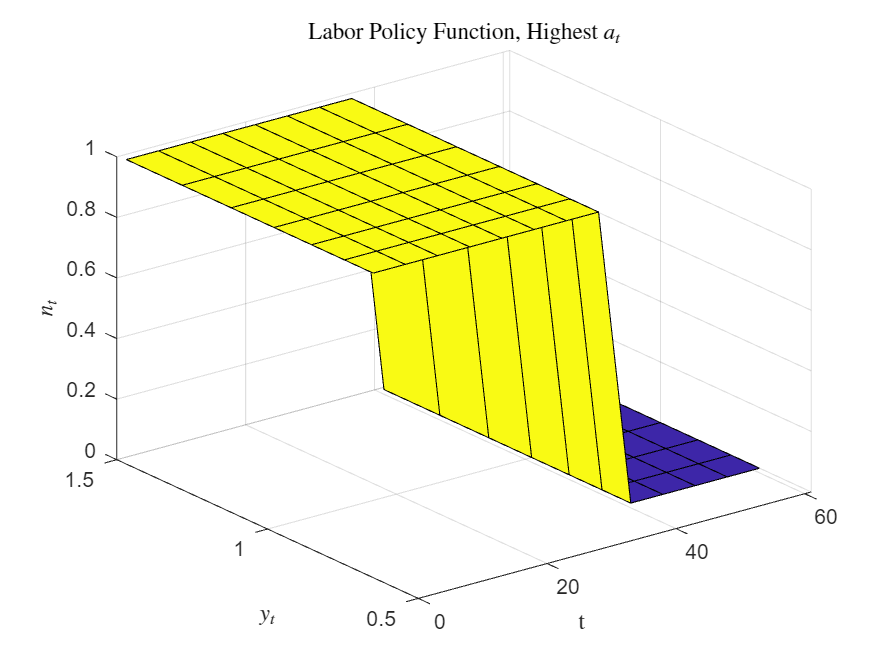

sim = simulate.lc(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.

% Parameters
betas = [0.90, 0.92, 0.94, 0.96];
gamma = 2.00; % Corrected gamma value
age = 1:61;
colors = lines(length(betas)); % Color palette

% === Figure 1: Consumption Profiles ===
figure; hold on;
for i = 1:length(betas)
    % Initialize parameters
    par = model.setup();
    par.beta = betas(i);
    par.gamma = gamma; % Corrected gamma value
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Calculate average consumption for each age
    avg_c = nan(par.T,1);
    for t = age
        avg_c(t) = mean(sim.csim(sim.tsim==t), 'omitnan');
    end

    % Plot consumption for this beta
    plot(age, avg_c, 'LineWidth', 1.5, 'DisplayName', sprintf('\\beta = %.2f', betas(i)), 'Color', colors(i,:));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


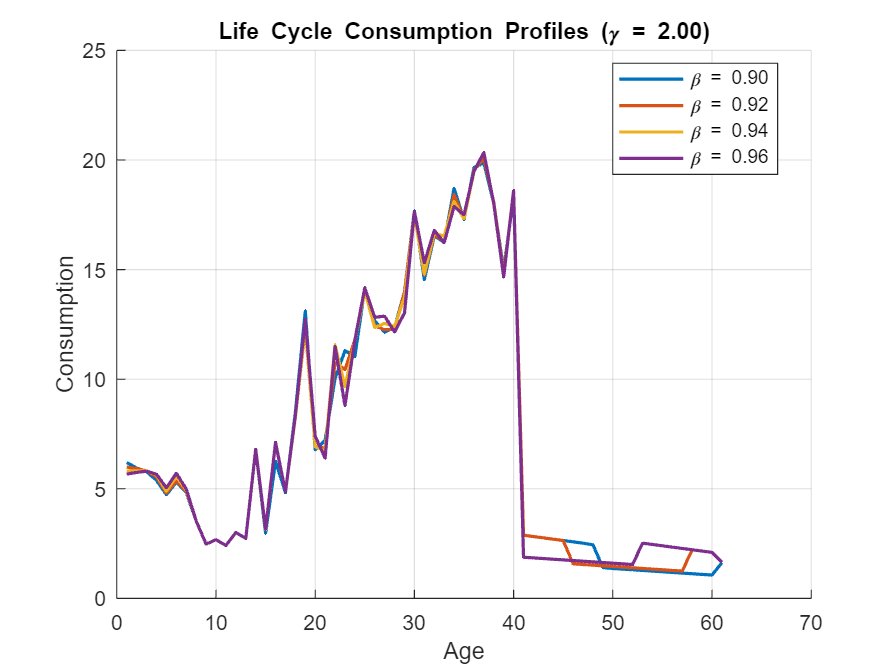

xlabel('Age'); ylabel('Consumption');
title('Life Cycle Consumption Profiles (\gamma = 2.00)');
legend('Location', 'best'); grid on;

% === Descriptive Stats Table for Avg Consumption Profiles (Plotted Data) ===
avg_consumption_profiles = nan(length(age), length(betas)); % [Age x Beta]

for i = 1:length(betas)
    % Initialize parameters
    par = model.setup();
    par.beta = betas(i);
    par.gamma = gamma;
    par = model.gen_grids(par);

    % Solve and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Average consumption at each age
    for t = age
        avg_consumption_profiles(t, i) = mean(sim.csim(sim.tsim == t), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



% Compute descriptive stats for plotted data
means_c = mean(avg_consumption_profiles, 1, 'omitnan');
stds_c  = std(avg_consumption_profiles, 0, 1, 'omitnan');
mins_c  = min(avg_consumption_profiles, [], 1);
maxs_c  = max(avg_consumption_profiles, [], 1);

% Create table
table_beta_consumption = table(betas', means_c', stds_c', mins_c', maxs_c', ...
    'VariableNames', {'Beta', 'Mean', 'Std', 'Min', 'Max'});

format shortG
disp('=== Descriptive Summary of Average Consumption by Age (Plotted Data) ===');

=== Descriptive Summary of Average Consumption by Age (Plotted Data) ===


disp(table_beta_consumption);

    Beta     Mean      Std       Min       Max  
    ____    ______    ______    ______    ______

     0.9    7.1927    6.0872    1.0643    19.871
    0.92    7.2173    6.0543    1.2454     20.08
    0.94    7.2504    6.0237    1.5467    20.345
    0.96    7.2546    6.0315    1.5467    20.337



% === Figure 2: Wealth Profiles ===
figure; hold on;
for i = 1:length(betas)
    % Initialize parameters
    par = model.setup();
    par.beta = betas(i);
    par.gamma = gamma; % Corrected gamma value
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Calculate average wealth for each age
    avg_a = nan(par.T,1);
    for t = age
        avg_a(t) = mean(sim.asim(sim.tsim==t), 'omitnan');
    end

    % Plot wealth for this beta
    plot(age, avg_a, 'LineWidth', 1.5, 'DisplayName', sprintf('\\beta = %.2f', betas(i)), 'Color', colors(i,:));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


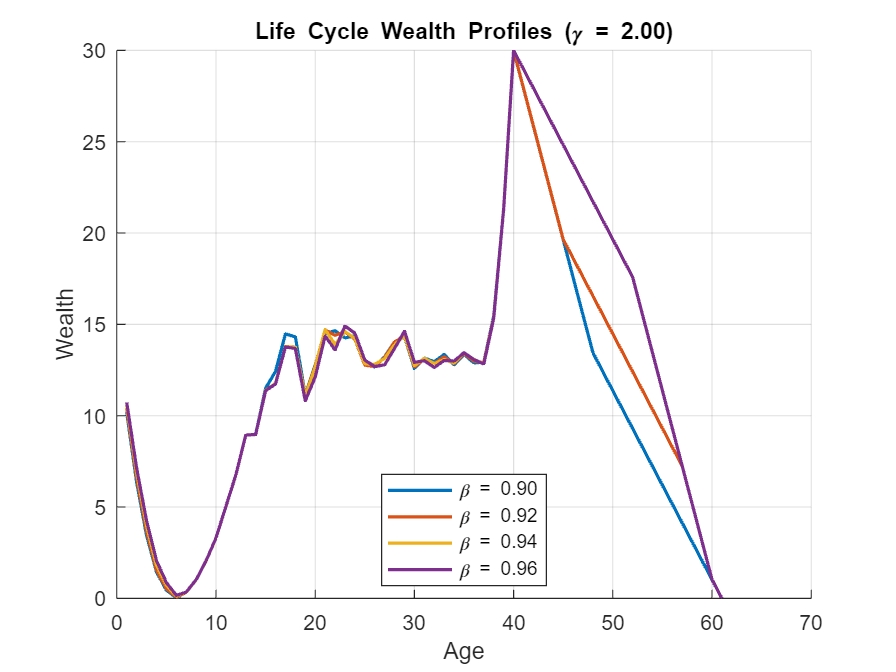

xlabel('Age'); ylabel('Wealth');
title('Life Cycle Wealth Profiles (\gamma = 2.00)');
legend('Location', 'best'); grid on;

% === Descriptive Stats Table for Avg Wealth Profiles (Plotted Data) ===
avg_wealth_profiles = nan(length(age), length(betas)); % [Age x Beta]

for i = 1:length(betas)
    % Initialize parameters
    par = model.setup();
    par.beta = betas(i);
    par.gamma = gamma;
    par = model.gen_grids(par);

    % Solve and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Average wealth at each age
    for t = age
        avg_wealth_profiles(t, i) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



% Compute descriptive stats for plotted data
means_a = mean(avg_wealth_profiles, 1, 'omitnan');
stds_a  = std(avg_wealth_profiles, 0, 1, 'omitnan');
mins_a  = min(avg_wealth_profiles, [], 1);
maxs_a  = max(avg_wealth_profiles, [], 1);

% Create table
table_beta_wealth = table(betas', means_a', stds_a', mins_a', maxs_a', ...
    'VariableNames', {'Beta', 'Mean', 'Std', 'Min', 'Max'});

format shortG
disp('=== Descriptive Summary of Average Wealth by Age (Plotted Data) ===');

=== Descriptive Summary of Average Wealth by Age (Plotted Data) ===


disp(table_beta_wealth);

    Beta     Mean      Std      Min     Max  
    ____    ______    ______    ___    ______

     0.9    11.094     6.912     0     29.984
    0.92    11.687    6.7967     0         30
    0.94    12.718    7.6878     0         30
    0.96    12.713    7.6695     0         30



% Parameters
beta = 0.96;  % Only beta = 0.96
gammas = [2.00, 3.00, 4.00, 5.00];  % Different gamma values
age = 1:61;
colors = lines(length(gammas));  % Color palette

avg_c = nan(length(gammas), 100);
avg_a = nan(length(gammas), 100);

% === Figure 1: Consumption Profiles ===
figure; hold on;
for g = 1:length(gammas)
    % Initialize parameters
    par = model.setup();
    par.beta = beta;
    par.sigma = gammas(g);  % Update gamma for each plot
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Calculate average consumption for each age
    avg_c = nan(par.T, 1);
    for t = age
        avg_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
    end

    % Plot consumption for this gamma and beta
    plot(age, avg_c, 'LineWidth', 1.5, 'DisplayName', sprintf('\\gamma = %.2f', gammas(g)), 'Color', colors(g, :));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


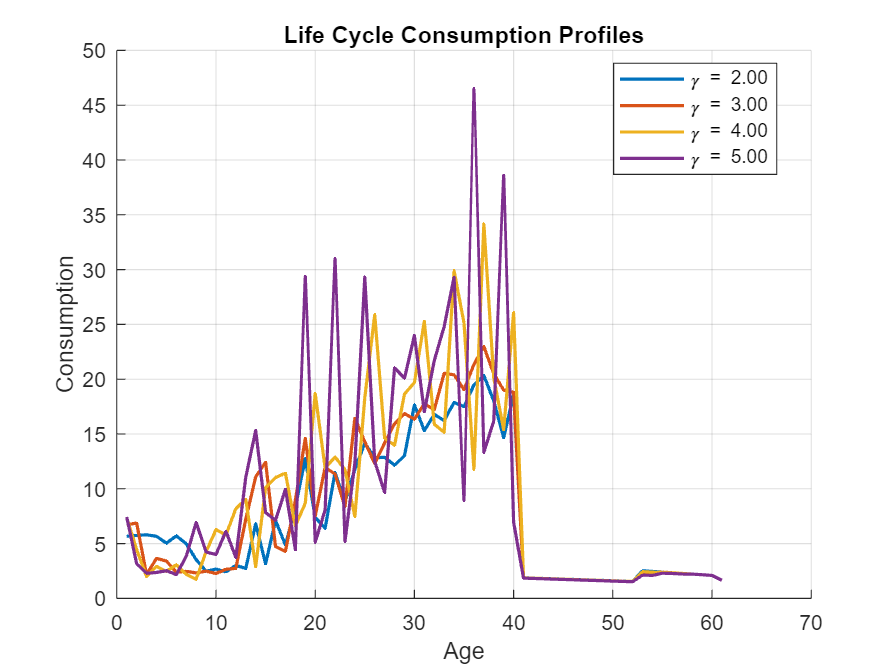

xlabel('Age'); ylabel('Consumption');
title('Life Cycle Consumption Profiles');
legend('Location', 'best'); grid on;

% === Descriptive Stats Table for Avg Consumption Profiles by Gamma ===
avg_c_profiles = nan(length(age), length(gammas));  % [Age x Gamma]

for g = 1:length(gammas)
    % Initialize parameters
    par = model.setup();
    par.beta = beta;
    par.sigma = gammas(g);  % Vary gamma
    par = model.gen_grids(par);

    % Solve and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Store avg consumption at each age
    for t = age
        avg_c_profiles(t, g) = mean(sim.csim(sim.tsim == t), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



% Compute descriptive stats
means_c = mean(avg_c_profiles, 1, 'omitnan');
stds_c  = std(avg_c_profiles, 0, 1, 'omitnan');
mins_c  = min(avg_c_profiles, [], 1);
maxs_c  = max(avg_c_profiles, [], 1);

% Create table
table_gamma_consumption = table(gammas', means_c', stds_c', mins_c', maxs_c', ...
    'VariableNames', {'Gamma', 'Mean', 'Std', 'Min', 'Max'});

format shortG
disp('=== Descriptive Summary of Avg Consumption by Gamma (Plotted Data) ===');

=== Descriptive Summary of Avg Consumption by Gamma (Plotted Data) ===


disp(table_gamma_consumption);

    Gamma     Mean      Std       Min       Max  
    _____    ______    ______    ______    ______

      2      7.2546    6.0315    1.5467    20.337
      3      7.9835    7.0503    1.5401    22.981
      4      8.9127    8.5055    1.5418    34.167
      5      9.4251    10.456     1.519    46.495



% Parameters
beta = 0.96;
gammas = [2.00, 3.00, 4.00, 5.00];
age = 1:61;
colors = lines(length(gammas)); % Unique colors for each gamma

% === Figure: Wealth Profiles ===
figure; hold on;
for g = 1:length(gammas)
    % Initialize parameters
    par = model.setup();
    par.beta = beta;
    par.sigma = gammas(g);  % Update gamma for each plot
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Calculate average wealth for each age
    avg_a = nan(par.T, 1);
    for t = age
        avg_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    % Plot wealth line for this gamma
    plot(age, avg_a, 'LineWidth', 1.5, 'DisplayName', sprintf('\\gamma = %.2f', gammas(g)), ...
         'Color', colors(g, :));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


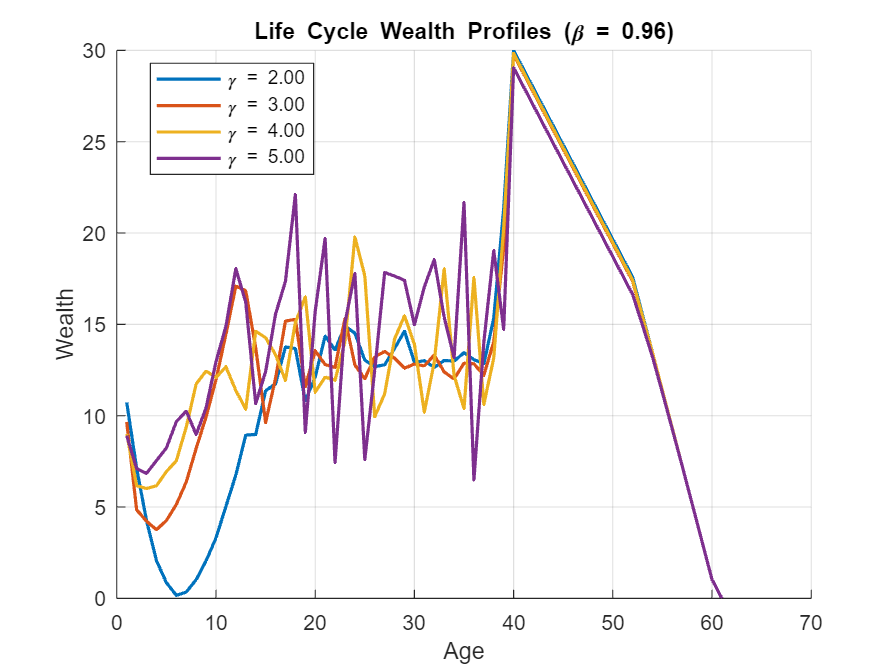

xlabel('Age'); ylabel('Wealth');
title('Life Cycle Wealth Profiles (\beta = 0.96)');
legend('Location', 'best'); grid on;

% === Descriptive Stats Table for Avg Wealth Profiles by Gamma ===
avg_a_profiles = nan(length(age), length(gammas));  % [Age x Gamma]

for g = 1:length(gammas)
    % Initialize parameters
    par = model.setup();
    par.beta = beta;
    par.sigma = gammas(g);
    par = model.gen_grids(par);

    % Solve and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Store avg wealth at each age
    for t = age
        avg_a_profiles(t, g) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



% Compute descriptive stats
means_a = mean(avg_a_profiles, 1, 'omitnan');
stds_a  = std(avg_a_profiles, 0, 1, 'omitnan');
mins_a  = min(avg_a_profiles, [], 1);
maxs_a  = max(avg_a_profiles, [], 1);

% Create table
table_gamma_wealth = table(gammas', means_a', stds_a', mins_a', maxs_a', ...
    'VariableNames', {'Gamma', 'Mean', 'Std', 'Min', 'Max'});

format shortG
disp('=== Descriptive Summary of Avg Wealth by Gamma (Plotted Data) ===');

=== Descriptive Summary of Avg Wealth by Gamma (Plotted Data) ===


disp(table_gamma_wealth);

    Gamma     Mean      Std      Min     Max  
    _____    ______    ______    ___    ______

      2      12.713    7.6695     0         30
      3      13.652      6.72     0     29.772
      4      14.064     6.593     0     29.833
      5      14.645    6.5656     0     29.049



% Consumption and wealth graphs with varied parameters
gamma_vals = [1.00, 2.00, 3.00, 4.00];
nu_vals = [0.5, 1.0, 1.5, 2.00];
gamma_fixed = 2.00;
nu_fixed = 0.5;

% Initialize model parameters
par0 = model.setup();
T = par0.T;

% Preallocate storage for results
avg_c = nan(length(gamma_vals), T);
avg_a = nan(length(gamma_vals), T);

% Loop over different values of gamma
for idx = 1:length(gamma_vals)
    % Setup model for each gamma value
    par = model.setup();
    par.nu = nu_fixed;
    par.gamma = gamma_vals(idx);
    
    % Generate grids for the model
    par = model.gen_grids(par);
    
    % Solve and simulate the model
    solution = solve.lc(par);
    simulation = simulate.lc(par, solution);
    
    % Compute the averages for consumption and wealth at each time step
    for time_step = 1:T
        avg_c(idx, time_step) = mean(simulation.csim(simulation.tsim == time_step), 'omitnan');
        avg_a(idx, time_step) = mean(simulation.asim(simulation.tsim == time_step), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


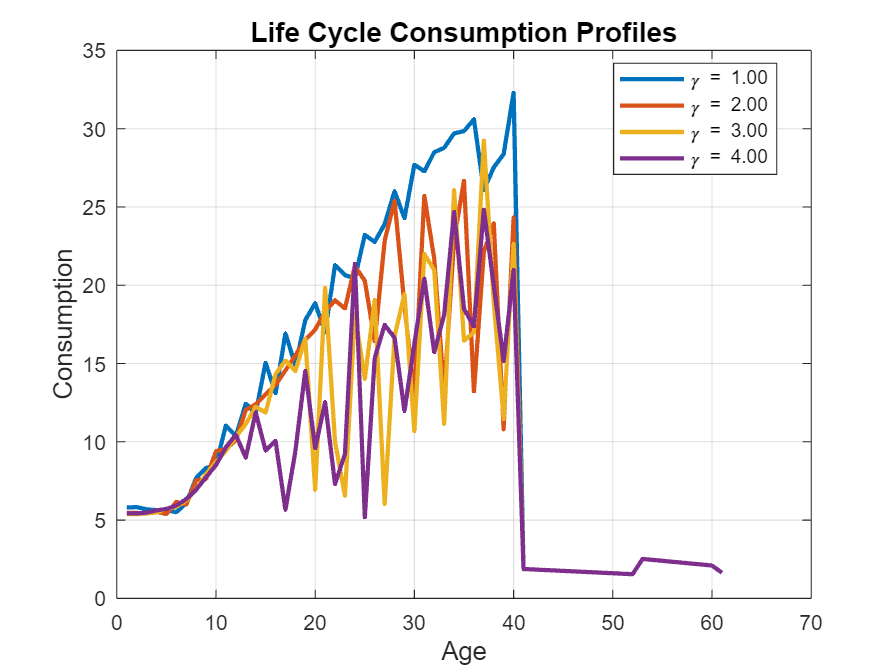

% Plot: Average Consumption
figure;
hold on;

% Use color scheme
color_scheme = lines(length(gamma_vals));

for idx = 1:length(gamma_vals)
    plot(1:T, avg_c(idx, :), ...
        'LineWidth', 2, ...
        'Color', color_scheme(idx, :), ...
        'DisplayName', sprintf('\\gamma = %.2f', gamma_vals(idx)));
end

hold off;
xlabel('Age', 'FontSize', 12);
ylabel('Consumption', 'FontSize', 12);
title('Life Cycle Consumption Profiles', 'FontSize', 13);
legend('Location', 'best');
grid on;
box on;

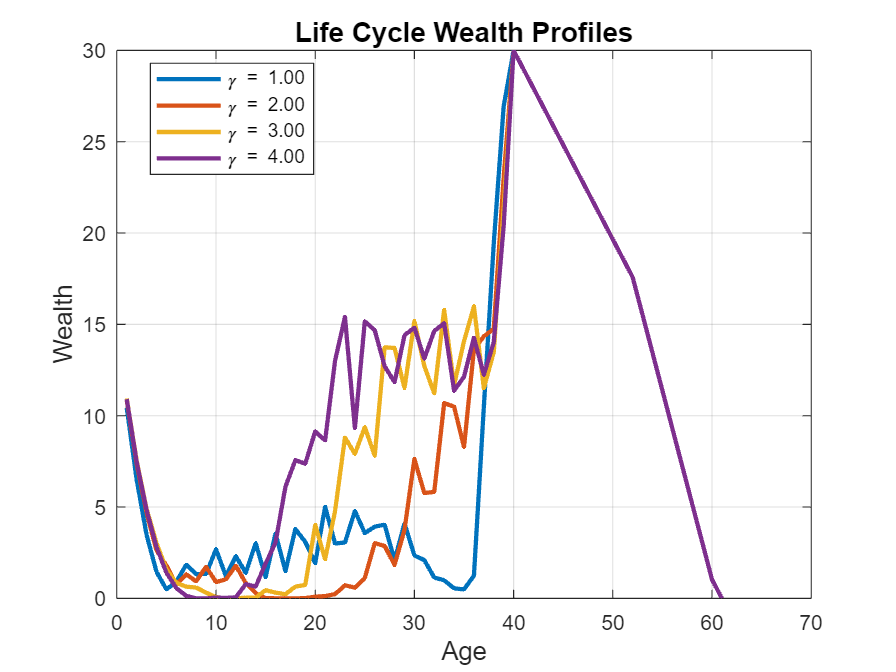

% Plot: Average Wealth
figure;
hold on;

% Use the same color scheme as for consumption
color_scheme = lines(length(gamma_vals));

for idx = 1:length(gamma_vals)
    plot(1:T, avg_a(idx, :), ...
        'LineWidth', 2, ...
        'Color', color_scheme(idx, :), ...
        'DisplayName', sprintf('\\gamma = %.2f', gamma_vals(idx)));
end

hold off;
xlabel('Age', 'FontSize', 12);
ylabel('Wealth', 'FontSize', 12);
title('Life Cycle Wealth Profiles', 'FontSize', 13);
legend('Location', 'best');
grid on;
box on;

% === Descriptive Statistics Table ===
mean_c = mean(avg_c, 2, 'omitnan');
std_c  = std(avg_c, 0, 2, 'omitnan');
min_c  = min(avg_c, [], 2);
max_c  = max(avg_c, [], 2);

mean_a = mean(avg_a, 2, 'omitnan');
std_a  = std(avg_a, 0, 2, 'omitnan');
min_a  = min(avg_a, [], 2);
max_a  = max(avg_a, [], 2);

% Create table
des_tab = table(gamma_vals(:), ...
    mean_c, std_c, min_c, max_c, ...
    mean_a, std_a, min_a, max_a, ...
    'VariableNames', {'gamma', ...
                      'mean_consumption', 'std_consumption', 'min_consumption', 'max_consumption', ...
                      'mean_wealth', 'std_wealth', 'min_wealth', 'max_wealth'});

% Display in command window
disp('Descriptive Statistics for Consumption and Wealth by Gamma Value:');

Descriptive Statistics for Consumption and Wealth by Gamma Value:


disp(des_tab);

    gamma    mean_consumption    std_consumption    min_consumption    max_consumption    mean_wealth    std_wealth    min_wealth    max_wealth
    _____    ________________    _______________    _______________    _______________    ___________    __________    __________    __________

      1           12.523             10.548             1.5467             32.299            8.661         9.4066          0               30  
      2           10.449             8.2238             1.5467             26.672           8.8749         9.3895          0               30  
      3           9.2267             7.3722             1.5467             29.246           10.416         8.9929    

% Consumption graphs with varied nu, fixed gamma = 2.00
nu_vals = [0.5, 1.0, 1.5, 2.00];
gamma_fixed = 2.00;

% Initialize model parameters
par0 = model.setup();
T = par0.T;

% Preallocate storage for results
avg_c_nu = nan(length(nu_vals), T);

% Loop over different values of nu
for idx = 1:length(nu_vals)
    % Setup model for each nu value
    par = model.setup();
    par.gamma = gamma_fixed;
    par.nu = nu_vals(idx);
    
    % Generate grids for the model
    par = model.gen_grids(par);
    
    % Solve and simulate the model
    solution = solve.lc(par);
    simulation = simulate.lc(par, solution);
    
    % Compute the averages for consumption at each time step
    for time_step = 1:T
        avg_c_nu(idx, time_step) = mean(simulation.csim(simulation.tsim == time_step), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


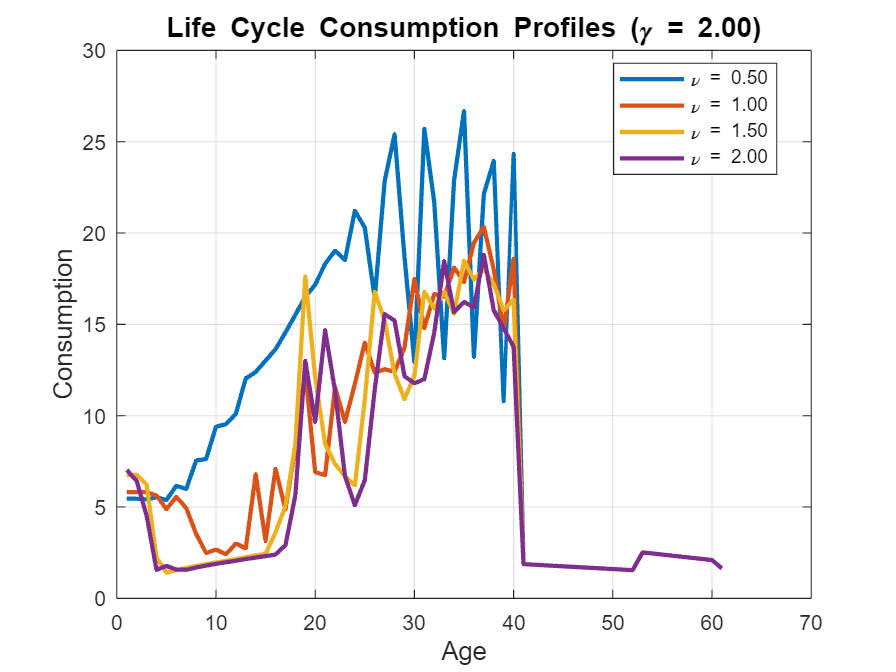


% Plot: Average Consumption by nu
figure;
hold on;

% Use color scheme
color_scheme = lines(length(nu_vals));

for idx = 1:length(nu_vals)
    plot(1:T, avg_c_nu(idx, :), ...
        'LineWidth', 2, ...
        'Color', color_scheme(idx, :), ...
        'DisplayName', sprintf('\\nu = %.2f', nu_vals(idx)));
end

hold off;
xlabel('Age', 'FontSize', 12);
ylabel('Consumption', 'FontSize', 12);
title('Life Cycle Consumption Profiles (\gamma = 2.00)', 'FontSize', 13);
legend('Location', 'best');
grid on;
box on;

% Wealth graphs with varied nu, fixed gamma = 2.00
nu_vals = [0.5, 1.0, 1.5, 2.00];
gamma_fixed = 2.00;

% Initialize model parameters
par0 = model.setup();
T = par0.T;

% Preallocate storage for results
avg_a_nu = nan(length(nu_vals), T);

% Loop over different values of nu
for idx = 1:length(nu_vals)
    % Setup model for each nu value
    par = model.setup();
    par.gamma = gamma_fixed;
    par.nu = nu_vals(idx);
    
    % Generate grids for the model
    par = model.gen_grids(par);
    
    % Solve and simulate the model
    solution = solve.lc(par);
    simulation = simulate.lc(par, solution);
    
    % Compute the averages for wealth at each time step
    for time_step = 1:T
        avg_a_nu(idx, time_step) = mean(simulation.asim(simulation.tsim == time_step), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


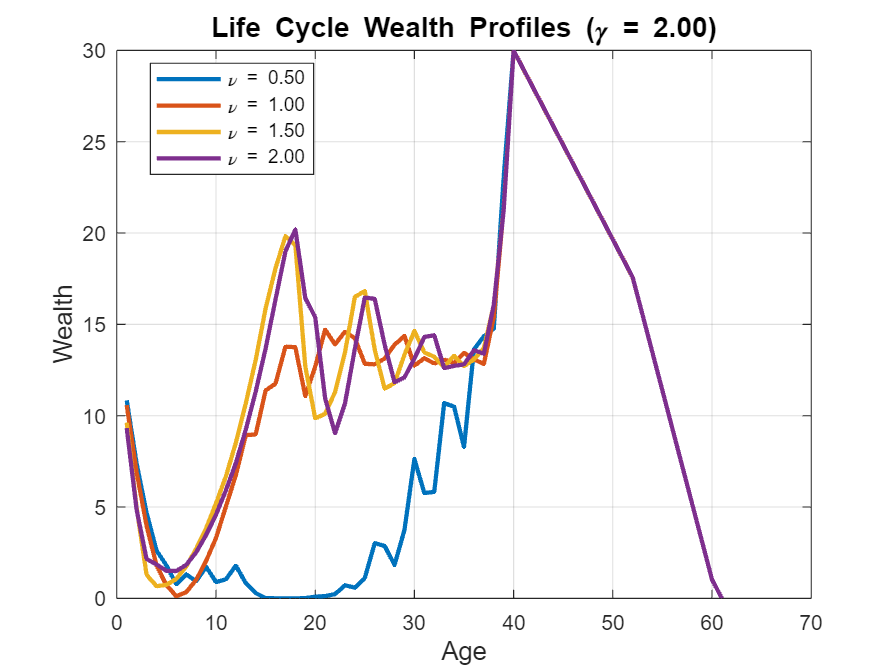


% Plot: Average Wealth by nu
figure;
hold on;
color_scheme = lines(length(nu_vals)); % Color scheme

for idx = 1:length(nu_vals)
    plot(1:T, avg_a_nu(idx, :), ...
        'LineWidth', 2, ...
        'Color', color_scheme(idx,:), ...
        'DisplayName', sprintf('\\nu = %.2f', nu_vals(idx)));
end
hold off;
xlabel('Age', 'FontSize', 12);
ylabel('Wealth', 'FontSize', 12);
title('Life Cycle Wealth Profiles (\gamma = 2.00)', 'FontSize', 13);
legend('Location', 'best');
grid on;
box on;

% === Descriptive Statistics for Consumption and Wealth ===
% Consumption: Mean, Std, Min, Max
mean_c_nu = mean(avg_c_nu, 2, 'omitnan');
std_c_nu  = std(avg_c_nu, 0, 2, 'omitnan');
min_c_nu  = min(avg_c_nu, [], 2);
max_c_nu  = max(avg_c_nu, [], 2);

% Wealth: Mean, Std, Min, Max
mean_a_nu = mean(avg_a_nu, 2, 'omitnan');
std_a_nu  = std(avg_a_nu, 0, 2, 'omitnan');
min_a_nu  = min(avg_a_nu, [], 2);
max_a_nu  = max(avg_a_nu, [], 2);

% Combine Consumption and Wealth Descriptive Statistics into one table
des_tab_combined = table(nu_vals(:), ...
    mean_c_nu, std_c_nu, min_c_nu, max_c_nu, ...
    mean_a_nu, std_a_nu, min_a_nu, max_a_nu, ...
    'VariableNames', {'nu', ...
                      'mean_consumption', 'std_consumption', 'min_consumption', 'max_consumption', ...
                      'mean_wealth', 'std_wealth', 'min_wealth', 'max_wealth'});

% Display the combined descriptive statistics table
disp('Combined Descriptive Statistics for Consumption and Wealth by nu:');

Combined Descriptive Statistics for Consumption and Wealth by nu:


disp(des_tab_combined);

    nu     mean_consumption    std_consumption    min_consumption    max_consumption    mean_wealth    std_wealth    min_wealth    max_wealth
    ___    ________________    _______________    _______________    _______________    ___________    __________    __________    __________

    0.5         10.449             8.2238             1.5467             26.672           8.8749         9.3895          0               30  
      1         7.2504             6.0237             1.5467             20.345           12.718         7.6878          0               30  
    1.5         6.6607             6.0849             1.4104             18.481           13.187         7.7316          0   

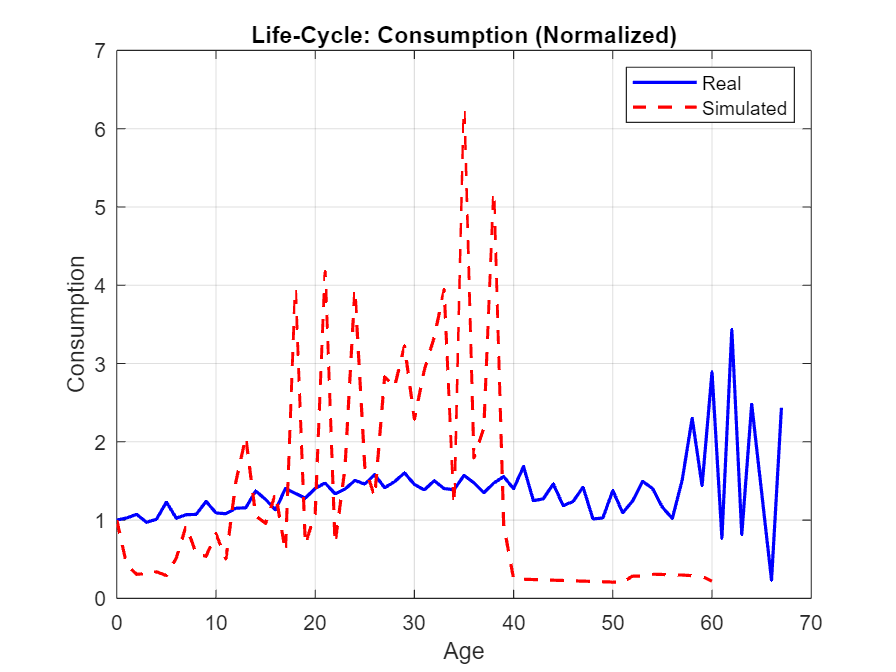

% === Load real data ===
real_data = readtable("final_output_new.csv");

% Shift age so that it starts from 0
min_age = min(real_data.age);
real_data.age_norm = real_data.age - min_age;

% === Compute lifecycle profiles from real data (group first!) ===
G = groupsummary(real_data, "age_norm", "mean", ...
    ["household_consumption2", "total_wealth", "average_work_hours_y"]);

% Rename and extract into real_profiles
real_profiles = table;
real_profiles.age        = G.age_norm;
real_profiles.avg_cons   = G.mean_household_consumption2;
real_profiles.avg_wealth = G.mean_total_wealth;
real_profiles.avg_hours  = G.mean_average_work_hours_y / (260*16);  

% Normalize real consumption and wealth using age‐0 values
real_profiles.avg_cons   = real_profiles.avg_cons   / real_profiles.avg_cons(1);
real_profiles.avg_wealth = real_profiles.avg_wealth / real_profiles.avg_wealth(1);

% === Simulated Data ===
T = par.T;
sim_profiles = table((0:T-1)', 'VariableNames', {'age'});

for t = 1:T
    sim_profiles.avg_cons(t,1)   = mean(sim.csim(sim.tsim == t), 'omitnan');
    sim_profiles.avg_wealth(t,1) = mean(sim.asim(sim.tsim == t), 'omitnan');  
    sim_profiles.avg_hours(t,1)  = mean(sim.nsim(sim.tsim == t), 'omitnan'); 
end

% Normalize simulated consumption only
sim_profiles.avg_cons = sim_profiles.avg_cons / sim_profiles.avg_cons(1);

% === Plot 1: Consumption (Normalized) ===
figure;
plot(real_profiles.age, real_profiles.avg_cons, 'b-', 'LineWidth', 1.5); hold on;
plot(sim_profiles.age, sim_profiles.avg_cons, 'r--', 'LineWidth', 1.5);
title('Life-Cycle: Consumption (Normalized)');
xlabel('Age'); ylabel('Consumption');
legend('Real', 'Simulated'); grid on;

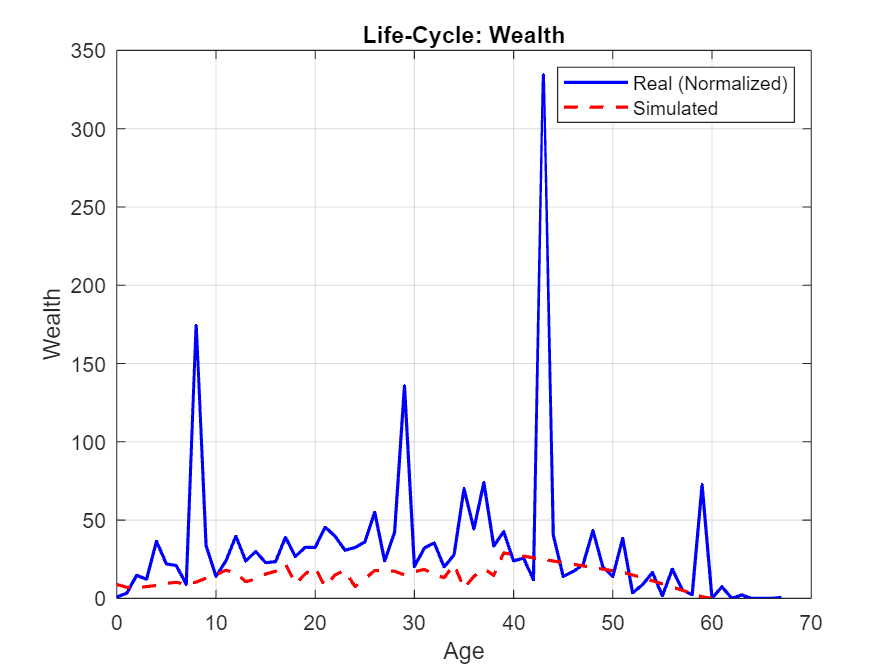


% === Plot 2: Wealth (Real = Normalized, Sim = Raw) ===
figure;
plot(real_profiles.age, real_profiles.avg_wealth, 'b-', 'LineWidth', 1.5); hold on;
plot(sim_profiles.age, sim_profiles.avg_wealth, 'r--', 'LineWidth', 1.5);
title('Life-Cycle: Wealth');
xlabel('Age'); ylabel('Wealth');
legend('Real (Normalized)', 'Simulated'); grid on;

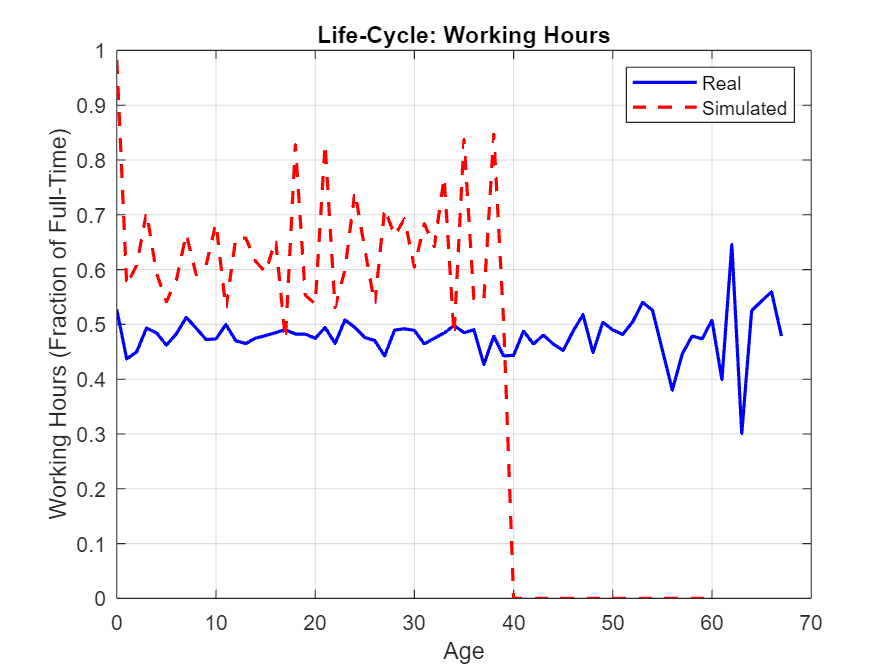


% === Plot 3: Working Hours (Normalized by 240) ===
figure;
plot(real_profiles.age, real_profiles.avg_hours, 'b-', 'LineWidth', 1.5); hold on;
plot(sim_profiles.age, sim_profiles.avg_hours, 'r--', 'LineWidth', 1.5);
title('Life-Cycle: Working Hours');
xlabel('Age'); ylabel('Working Hours (Fraction of Full-Time)');
legend('Real', 'Simulated'); grid on;

% === Descriptive Statistics for Real Data ===
real_means = [mean(real_profiles.avg_cons), mean(real_profiles.avg_wealth), mean(real_profiles.avg_hours)];
real_stds  = [std(real_profiles.avg_cons), std(real_profiles.avg_wealth), std(real_profiles.avg_hours)];

% === Descriptive Statistics for Simulated Data ===
sim_means = [mean(sim_profiles.avg_cons), mean(sim_profiles.avg_wealth), mean(sim_profiles.avg_hours)];
sim_stds  = [std(sim_profiles.avg_cons), std(sim_profiles.avg_wealth), std(sim_profiles.avg_hours)];

% === Create a table with both real and simulated data statistics ===
stats_table = table(...
    real_means', real_stds', sim_means', sim_stds', ...
    'VariableNames', {'Mean_Real', 'Std_Dev_Real', 'Mean_Sim', 'Std_Dev_Sim'}, ...
    'RowNames', {'Consumption', 'Wealth', 'Working Hours'});  % 3 row names for the 3 variables

% Display the final table
disp('=== Descriptive Statistics Comparison ===');

=== Descriptive Statistics Comparison ===


disp(stats_table);

                     Mean_Real    Std_Dev_Real    Mean_Sim    Std_Dev_Sim
                     _________    ____________    ________    ___________

    Consumption        1.3777        0.46192       1.2679        1.4066  
    Wealth             33.177         46.943       14.645        6.5656  
    Working Hours     0.47912       0.041758      0.42012       0.31991  

